# Support vector regression (using Gaussain Kernel Dataset:GaussaianData)

## Initailization

clear all;clc;

% Zscore Normalization
data=zscore(csvread('GaussaianData.csv'));

% Input -> x, Output -> y
x=data(:,1:end-1);
y=data(:,end);

% Number of data points
N=length(data);

alpha=zeros(N,1);

% Tolerence value
norm1=Inf; tol=10e-1;

% Maximum number of iterations
itr=0; maxItr=10e2;
eps=0.1;

## Algorithm

while (norm1>tol && itr<maxItr)
    alpha_old=alpha;
    alpha_=alpha;
    for i=1:N
        alpha(i)=alpha(i) + y(i) -eps*sign(alpha(i))...
            -alpha'*kernel(x,x(i,:),'g')';
        
        if alpha_(i)*alpha(i)<0
            alpha(i)=0;
        end
        
    end
norm1=norm(alpha_old-alpha);
itr=itr+1;
end
fprintf('Total number of iteration %d',itr)

Total number of iteration 100

## Weights

w=sum(alpha.*x)

w =    -1.5250   -1.3856


## Bias

b=mean(y-(w*x')' -eps*ones(N,1))

b = -0.1000

## Predicted values

for j=1:N
    fx1(j,:)=alpha(j)*kernel(x,x(j,:),'g')';
end
fx=sum(fx1)';

disp('[Actual Values  Predicted Values]')

[Actual Values  Predicted Values]


disp([y(1:10) ,fx(1:10)])

    0.1834    0.0051
   -1.0830   -0.9915
   -1.0820   -0.9938
   -0.8228   -0.7516
   -0.4720   -0.4406
   -0.8747   -0.8104
    1.3743    1.2526
    1.3125    1.2030
    1.4929    1.3649
   -0.0881   -0.0261



## Mean Square error (Gaussian Kernel)

mse=norm(y-fx)^2/N

mse = 0.0132

## Plotting

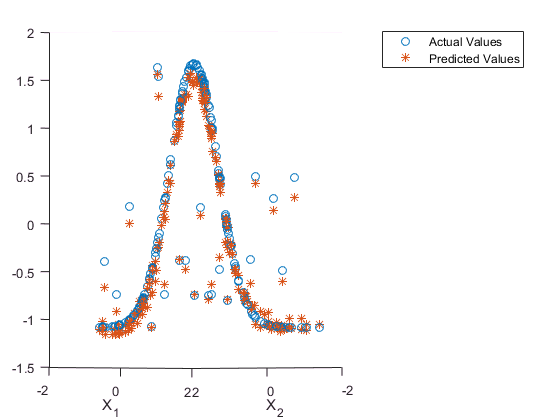

figure
hold on
scatter3(x(:,1),x(:,2),y)
scatter3(x(:,1),x(:,2),fx,'*')
hold off
xlabel({'X_1'});
ylabel({'X_2'});
view([-46.4 -0.40]);
legend1 = legend('Actual Values','Predicted Values');

% Bhartendu, Machine Learning & computing